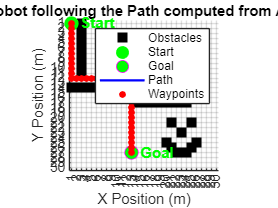

% Simulating Unicycle robot with path from A*

% Parameters
x = startNode(1);           % Initial x position from A* startNode
y = startNode(2);           % Initial y position from A* startNode
theta = 0;                  % Initial orientation

% Controller gains
k_v = 1;                  % Proportional gain for linear velocity
k_omega = 5;                % Proportional gain for angular velocity

% Simulation parameters
dt = 0.01;
max_time = 50;              % Adjust simulation duration as needed
t = 0:dt:max_time;

% Path from A* as waypoints
waypoints = path;           % Import waypoints as (x, y) from A* 'path' variable

% Preallocate memory (large enough for worst-case scenario)
max_steps = length(t) * size(waypoints, 1); % Rough estimate of total steps
x_history = zeros(1, max_steps);
y_history = zeros(1, max_steps);
theta_history = zeros(1, max_steps);

% Index to track actual size
idx = 1;

% Loop through waypoints from A*
for wp = 1:size(waypoints, 1)
    % Set target for the current waypoint
    x_target = waypoints(wp, 1);
    y_target = waypoints(wp, 2);
    
    while true
        % Calculate error in position and angle
        e_x = x_target - x;
        e_y = y_target - y;
        e_distance = sqrt(e_x^2 + e_y^2);
        e_angle = atan2(e_y, e_x) - theta;
        e_angle = atan2(sin(e_angle), cos(e_angle)); % Wrap angle to [-pi, pi]
        
        % Control law to determine v and omega
        v = k_v * e_distance;  % Linear velocity proportional to distance
        omega = k_omega * e_angle;  % Angular velocity proportional to angle error
        
        % Update pose using unicycle kinematics
        x = x + v * cos(theta) * dt;
        y = y + v * sin(theta) * dt;
        theta = theta + omega * dt;
        
        % Store data for plotting
        x_history(idx) = x;
        y_history(idx) = y;
        theta_history(idx) = theta;
        idx = idx + 1; % Move to the next index

        
        % Check if close to current waypoint
        if e_distance < 0.1
            break; % Move to the next waypoint
        end
    end
end

%trimming excess memory
x_history = x_history(1:idx-1);
y_history = y_history(1:idx-1);
theta_history = theta_history(1:idx-1);


% Plot the robot's path, waypoints, and obstacles
figure;
hold on;

% Correct obstacle coordinates from the environment matrix
[x_obstacles, y_obstacles] = find(environment == 1); % Extract obstacles directly without transpose
h1 = plot(x_obstacles, y_obstacles, 'ks', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); % Black squares for obstacles

% Highlight start and goal points
h2 = plot(waypoints(1,1), waypoints(1,2), 'go', 'MarkerSize', 9, 'MarkerFaceColor', 'g'); % Start point
h3 = plot(waypoints(end,1), waypoints(end,2), 'mo', 'MarkerSize', 9, 'MarkerFaceColor', 'g'); % Goal point

% Add labels for start and goal points
text(waypoints(1,1), waypoints(1,2), '  Start', 'FontSize', 10, 'Color', 'g', 'FontWeight', 'bold');
text(waypoints(end,1), waypoints(end,2), '  Goal', 'FontSize', 10, 'Color', 'g', 'FontWeight', 'bold');

% Plot the robot's path
h4 = plot(x_history, y_history, 'b-', 'LineWidth', 1.5); % Blue line for path

% Plot the waypoints
h5 = plot(waypoints(:,1), waypoints(:,2), 'ro', 'MarkerSize', 4, 'MarkerFaceColor', 'r'); % Red circles for waypoints

% Formatting
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Unicycle robot following the Path computed from A* algorithm');

% Correct legend with matching colors and markers
legend([h1, h2, h3, h4, h5], 'Obstacles', 'Start', 'Goal','Path', 'Waypoints');

grid on;

% Invert Y-axis for top-to-bottom visualization
set(gca, 'YDir', 'reverse'); % Make Y-axis increase from top to bottom
axis equal tight; % Keep axes equally scaled and fit to data

axis equal tight;  % Equal scaling
set(gca, 'XTick', 1:gridSize(1), 'YTick', 1:gridSize(2)); % Setting ticks to match grid cells
set(gca, 'XLim', [0.5, gridSize(1) + 0.5], 'YLim', [0.5, gridSize(2) + 0.5]); % Fitting grid boundaries